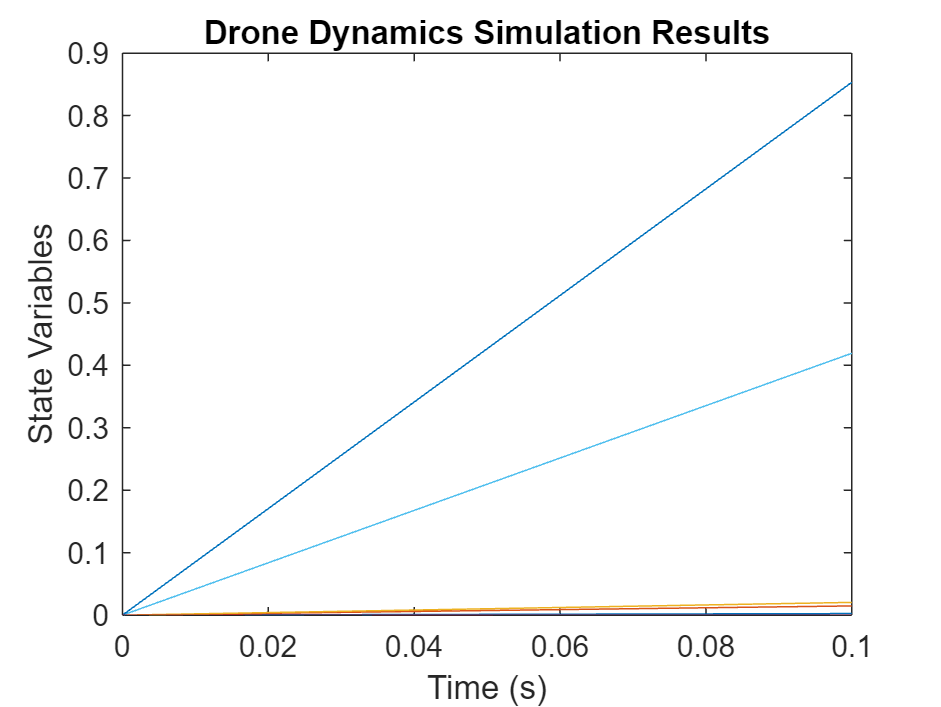

syms pn pe pd u v w phi theta psi p q r Z_T_c L_T_c M_T_c N_T_c real;
% FL nFR nRL nRR  

% Constants
p_row = 1.225; % Air density (kg/m^3)
D = 0.045; % Propeller diameter (m)
g = 9.81; % Gravitational acceleration (m/s^2)
m = 0.042; % kg mass of drone
Ct_least_squares = 0.1731; 
Cp_least_squares = 1979; 
Distance_to_pitch_axis = 0.0651; 
distance_to_roll_axis_m = 0.0651;
% n_motors = [nFL; nFR; nRL; nRR]; % For B Matrix 
omega = [p; q; r]; % omega_B_E, 
v_b = [u; v; w]; % angular velocity 


% calculate a, b, c, d 
a_value = p_row * Ct_least_squares * D^4 ; 
b_value = p_row * Ct_least_squares * distance_to_roll_axis_m * D^4; 
c_value = p_row * Ct_least_squares * distance_to_roll_axis_m * D^4; 
d_value = (p_row * Cp_least_squares * D^5)/(2 * pi); 

A = [-abs(a_value),-abs(a_value) -abs(a_value), -abs(a_value)]; 
B = [abs(b_value), -abs(b_value),-abs(b_value),  abs(b_value)]; 
C = [abs(c_value), abs(c_value), -abs(c_value), -abs(c_value)]; 
D = [-abs(d_value),abs(d_value), -abs(d_value),  abs(d_value)];

% Create M 
M = [A;...
     B;...
     C;...
     D]; 


% Mixer implementation: 

% Create inverse of M 
M_inv = inv(M); 

W_c_t = [Z_T_c; L_T_c; M_T_c; N_T_c];

motor_speeds_squared = M_inv \ W_c_t; % Equivalent to M_inv * W_c_t, just faster 

motor_speeds = sqrt(abs(motor_speeds_squared)); 

w_g_t = M * motor_speeds_squared; 

Mt = [motor_speeds(2);...
      motor_speeds(3);...
      motor_speeds(4)]; 

% Position Equation

% Define the Roll rotation matrix 
% Order of rotation Z, Y, X 
R_phi = [1, 0, 0;
         0, cos(phi), -sin(phi);
         0, -sin(phi), cos(phi)];

% Define the Pitch rotation matrix
R_theta = [cos(theta), 0, -sin(theta);
           0, 1, 0;
           sin(theta), 0, cos(theta)];

% Define the Yaw rotation matrix
R_psi = [cos(psi), sin(psi), 0;
         -sin(psi), cos(psi), 0;
         0, 0, 1];


% Compute the combined rotation matrix R_E_B
R_E_B = R_phi * R_theta * R_psi; 


% Components for the Equation of position
eqn_p_n_dot = R_E_B(1, :) * v_b;
eqn_p_e_dot = R_E_B(2, :) * v_b; 
eqn_p_d_dot = R_E_B(3, :) * v_b; 

% Inertia Matrix 

% Define the dimensions of the UAV (3D square box) using temporary
a = 0.11; % m
b = 0.11; % m
c = 0.029; % m

% Calculate the moment of inertia matrix I
Ixx = (1/12) * m * (b^2 + c^2);
Iyy = (1/12) * m * (a^2 + c^2);
Izz = (1/12) * m * (a^2 + b^2);

I = diag([Ixx, Iyy, Izz]); % Inertia matrix

% Rotational dynamics
omega_dot = inv(I) \ (Mt - cross(omega, I*omega));

% Total thrust

Ft = [0; 0; motor_speeds_squared(1)]; % Vector Form 

% force of gravity acting on the UAV in the body frame
F_g_b = R_E_B' * [0; 0; m*g];

% Define translational equations of motion
eqn_u_dot = (1/m) * (Ft + F_g_b(1)) - r*v + q*w;
eqn_v_dot = (1/m) * F_g_b(2) + r*u - p*w;
eqn_w_dot = (1/m) * F_g_b(3) - q*u + p*v;

translational_equations = [eqn_u_dot; eqn_v_dot; eqn_w_dot]; 

% Equation of position
eqn_p_n_dot = R_E_B(1, :) * v_b;
eqn_p_e_dot = R_E_B(2, :) * v_b; 
eqn_p_d_dot = R_E_B(3, :) * v_b; 

position_equation = [eqn_p_n_dot; eqn_p_e_dot; eqn_p_d_dot];

% Define angular equations of motion
% Define equation for roll_dot, pitch_dot, yaw_dot
H_inv = [1, sin(phi)*tan(theta), cos(phi)*tan(theta);...
                0, cos(phi), -sin(phi);...
                0, sin(phi)/cos(theta), cos(phi)/cos(theta)] ; 


% Define equation for roll_dot, pitch_dot, yaw_dot
dot_angles =  H_inv * omega; 

% Complete Equation of F
f = [position_equation;...
    translational_equations
    omega_dot;...
    dot_angles;...
    ];


% Generate the function file using matlabFunction
% droneDynamics = matlabFunction(f, 'File', 'DroneSimulation', 'Outputs', {'p_dot', 'v_dot', 'w_dot', 'theta_dot', 'motor_speeds'}, 'Vars', {Z_T_c, L_T_c, M_T_c, N_T_c});

droneDynamics = matlabFunction(f, 'File', 'DroneSimulation', 'Vars', {pn, pe, pd, u, v, w, phi, theta, psi, p, q, r, Z_T_c, L_T_c, M_T_c, N_T_c});




% Define the time span and initial conditions
T = [0, 0.1]; % Define the end time
initial_conditions = zeros(14,1); % Define the initial conditions array
% x_test = x(1), x(2), x(3), x(4), x(5), x(6), x(7), x(8), x(9), x(10), x(11), x(12), 50 , 50, 50, 50 ; % Initial Test

% Run the simulation
[t, z] = ode45(@(t, x) droneDynamics(x(1), x(2), x(3), x(4), x(5), x(6), x(7), x(8), x(9), x(10), x(11), x(12),  -g*m , 0, 0, 0 ), [0, T], initial_conditions);

% Plot the simulation results
plot(t, z);
xlabel('Time (s)');
ylabel('State Variables');
title('Drone Dynamics Simulation Results');


% Define the step size for Lc, Mc, and Nc
step_size = 0.004;

% Define the range for Lc, Mc, and Nc
Lc_range = 0:step_size:0.008; 
Mc_range = 0:step_size:0.008; 
Nc_range = 0:step_size:0.008; 

% Initialize an array to store the results
all_results = [];
all_labels = {};

% Define a common time vector (e.g., from 0 to T with fixed intervals)
common_t = linspace(0, 10, 1000); 

% Loop over each value of Lc, Mc, and Nc
for Lc = Lc_range
    for Mc = Mc_range
        for Nc = Nc_range
            % Run the simulation
            [t, z] = ode45(@(t, x) droneDynamics(x(1), x(2), x(3), x(4), x(5), x(6), x(7), x(8), x(9), x(10), x(11), x(12), -g*m, Lc, Mc, Nc), [0, T], initial_conditions);


            % Append the interpolated results
            all_results = [all_results; z];
            all_labels{end+1} = ['Lc = ', num2str(Lc), ', Mc = ', num2str(Mc), ', Nc = ', num2str(Nc)];
        end
    end
end

% Plot the accumulated results
figure;
plot(common_t, all_results);

Error using plot
Vectors must be the same length.

xlabel('Time (s)');
ylabel('State Variables');
title('Drone Dynamics Simulation Results');
legend(all_labels);
